# Different Edge Detections

This script compares the different edge detection algorithms on one frame, as wel as trying blur an histogram equalization to improve the edge detection

We concluded that edge detection using **zero crossing** us the best result gives after **blurring**

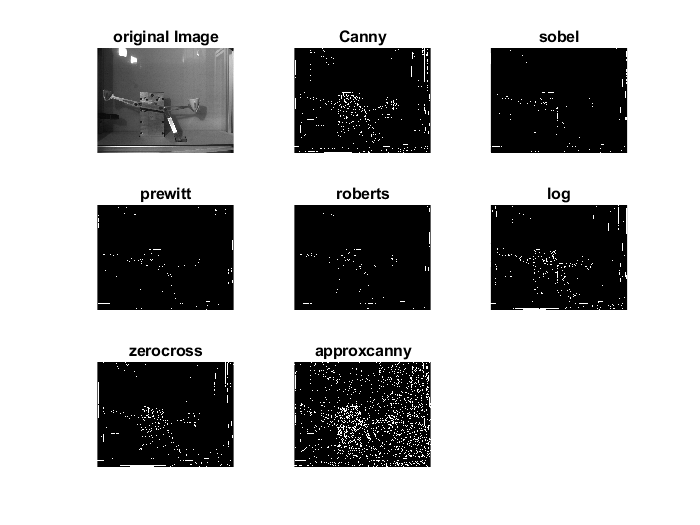

clear;
frame = load('Ballenwerper_sync_380fps_006.npychunk_3.mat').video_data;
frame = squeeze(frame);
frameBlur = imgaussfilt(frame, 2);
frameHist = histeq(frame);

imtool(frame)

figure;
subplot(3,3, 1)
imshow(frame)
title('original Image')

subplot(3,3, 2)
imshow(edge(frame, 'canny'))
title('Canny')

subplot(3,3, 3)
imshow(edge(frame, "sobel"))
title('sobel')

subplot(3,3, 4)
imshow(edge(frame, "prewitt"))
title('prewitt')

subplot(3,3, 5)
imshow(edge(frame, "roberts"))
title('roberts')

subplot(3,3, 6)
imshow(edge(frame, "log"))
title('log')

subplot(3,3, 7)
imshow(edge(frame, "zerocross"))
title('zerocross')

subplot(3,3, 8)
imshow(edge(frame, "approxcanny"))
title('approxcanny')

## Unblurred vs Blurred

figure, subplot(1,2,1)

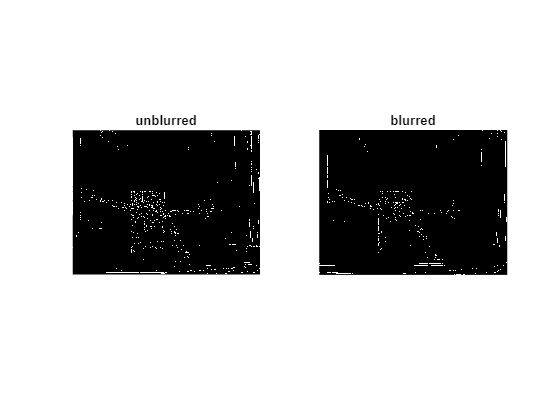

imshow(edge(frame, 'zerocross'))
title("unblurred")

subplot(1,2,2)
imshow(edge(frameBlur, 'zerocross'))
title("blurred")

## Equalization

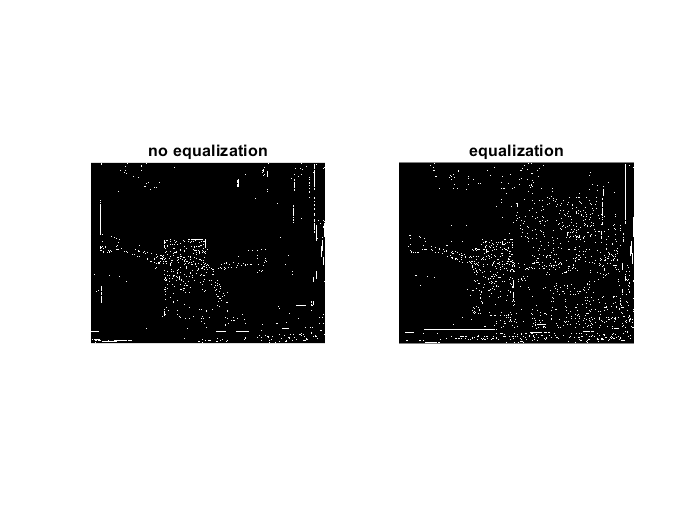

figure;
subplot(1,2,1)
imshow(edge(frame, 'zerocross'))
title("no equalization")

subplot(1,2,2)
imshow(edge(frameHist, 'zerocross'))
title("equalization")

## Testing labels

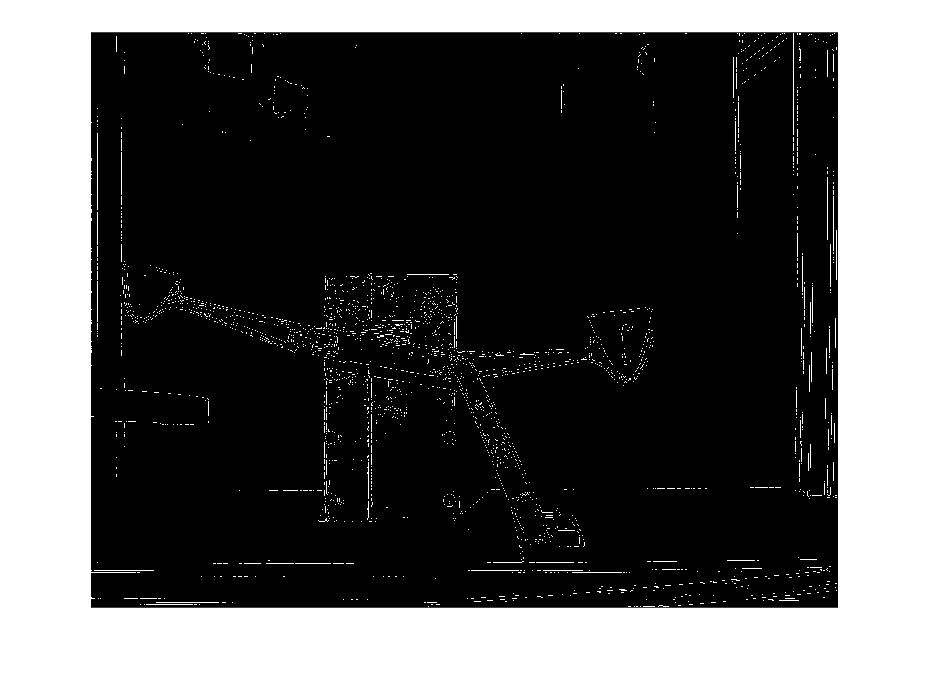

edges = edge(frameBlur, 'zerocross');
figure, imshow(edges)

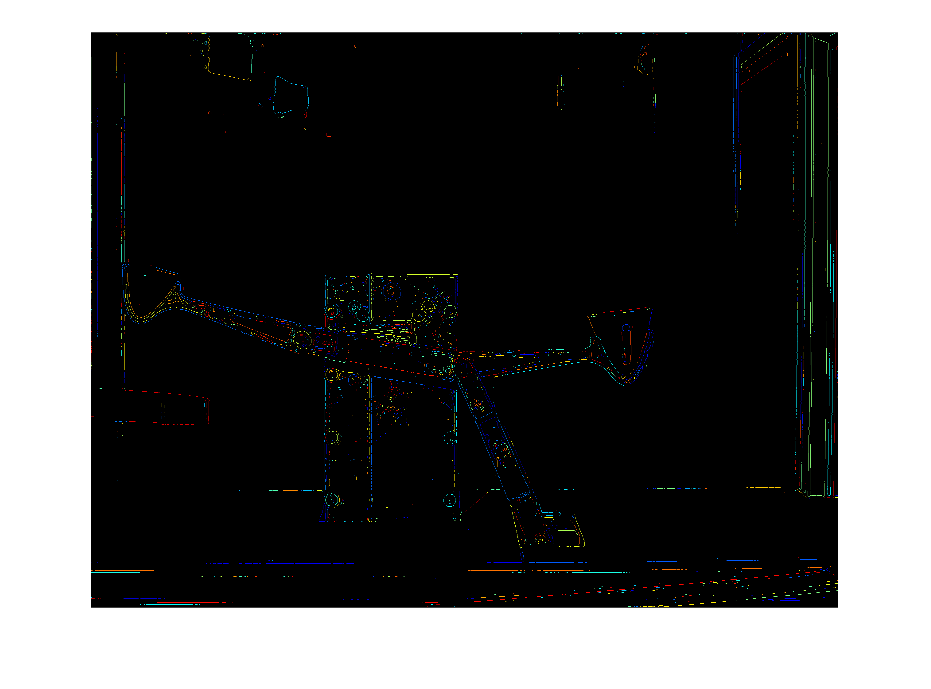

labeledImage = bwlabel(edges);
rgbLabeledImage = label2rgb(labeledImage, 'jet', 'k', 'shuffle'); % 'jet' colormap, 'k' background
figure, imshow(rgbLabeledImage);